% %% =====================================================================================================                 

#   **Data-driven decision-making and Maintenance 4.0**

% %======================================================================================================
% %                                         ILIAS OUACHTOUK
% %                                           1-2/04/2024
% %======================================================================================================

# TP2: Rolling Element Bearing Fault Diagnosis Using Machine Learning Classification.

This examples uses signal feature extraction objects to extract multidomain features that can be used to identify faulty bearing signals in mechanical systems. Feature extraction objects enable the computation of multiple features in an efficient way by reducing the number of times signals are transformed into a particular domain.

### **Introduction**

Rotating machines that use bearings are widely employed in various industrial applications, such as medical devices, food processing, semiconductor, paper making, and aircraft components. These industrial systems often suffer from electric current discharged through the bearings that can result in motor bearing failure within a few months of system startup. Failure to detect these issues in a timely manner can cause significant downtime in system operations. In addition to requiring regularly scheduled maintenance, the industrial system using rotating machines needs continuous monitoring for bearing current detection to ensure safety, reliability, efficiency, and performance.

Significant research work has been dedicated to automatic identification of faulty bearings in industrial systems. Recently, machine and deep learning algorithms have been used in fault analysis research [[1]](https://ieeexplore.ieee.org/document/8982045). Reliable, effective, and efficient feature extraction techniques play a key role in AI-based fault diagnosis performance. As the bearing current is caused by variable speed conditions, the fault frequencies can sweep up or down in the frequency range over time as the speed varies. In other words, bearing vibration signals are nonstationary in nature. The nonstationary characteristics can be captured well by various time-frequency representations. Combined features extracted from the time, frequency, and time-frequency representations of the signals can be used to improve the fault detection performance of systems.

####        [IMS Bearing Data  ](https://www.kaggle.com/datasets/vinayak123tyagi/bearing-dataset)

     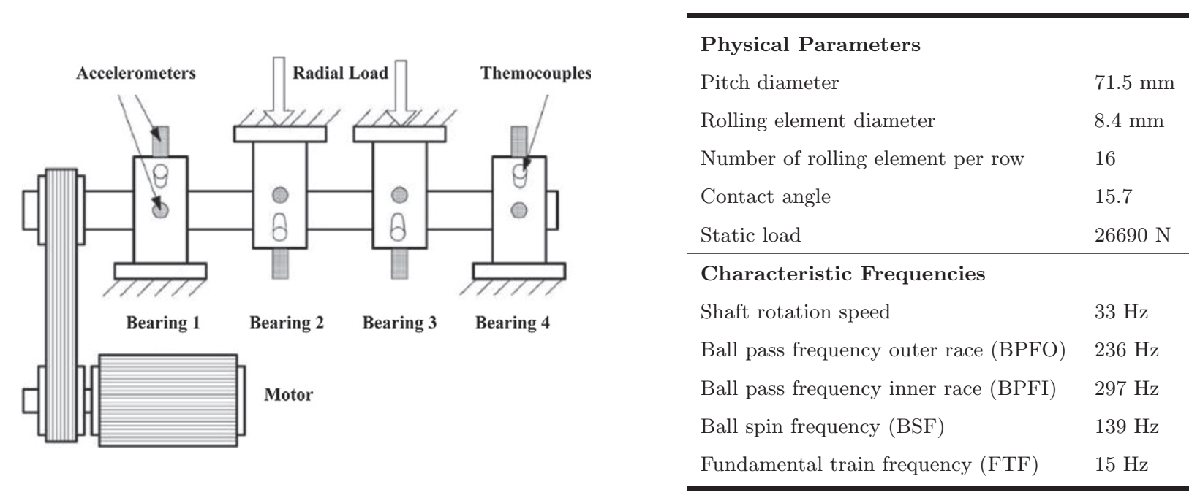

The data was generated by the NSF I/UCR Center for Intelligent Maintenance Systems (IMS – www.imscenter.net) with support from Rexnord Corp. in Milwaukee, WI. 

**Test Rig Setup:** Four bearings were installed on a shaft. The rotation speed was kept constant at 2000 RPM by an AC motor coupled to the shaft via rub belts. A radial load of 6000 lbs is applied onto the shaft and bearing by a spring mechanism. All bearings are force lubricated. 

Rexnord ZA-2115 double row bearings were installed on the shaft as shown in Figure 1. PCB 353B33 High Sensitivity Quartz ICP accelerometers were installed on the bearing housing (two accelerometers for each bearing [x- and y-axes] for data set 1, one accelerometer for each bearing for data sets 2 and 3). Sensor placement is also shown in Figure 1. All failures occurred after exceeding designed life time of the bearing which is more than 100 million revolutions.

% 

## Import the Data

The data set contains acceleration signals collected from rotating machines in bearing test rig. There are 200 files in total. The signals in the files are sampled at `fs` = 20 KHz. The file names describe the signals they contain:

- `healthy.mat` `—` 50 Healthy signals

- `innerfault.mat` `—` 50 Signals with inner race faults

- `outerfault.mat` `—` 50 Signals with outer race faults

- `ballfault.mat` `—` 50 Signals with ball faults

%% ========================================================================
%                            Initialisation
%==========================================================================
clear all,close all,clc;
%----------------------------- Load DATA ----------------------------------
load('Bearing_Data_IMS.mat');
addpath('Functions');  


%% ------------------------ Data Visualisation ----------------------------
xNormal=healthy(:,50);
xInner=innerfault(:,50);
xOuter=outerfault(:,50);
xBall=ballfault(:,50);

% Define the number of data points to be processed.
numSamples = length(xNormal);
% Define sampling frequency.
Fs = 20000;   % unit: Hz

%-----Define the parameters for the bearing-----
n = 16;         % Number of rolling element bearings
d = 8.4;   % Diameter of rolling elements 
pD = 71.5;     % Pitch diameter of bearing
thetaDeg = 15.7; % Contact angle in degrees
fr=33.3; %frequency by inveter



# `Visualizations`

## Examine vibration signals

**(Plot the healthy and faulty Vibration data)**

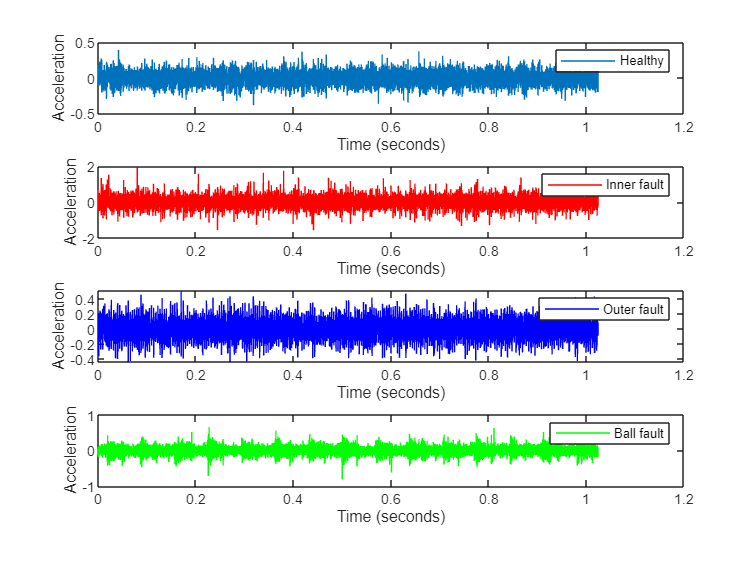

time =(0:numSamples-1)/Fs;
figure(1)
% healthy bearing signal
subplot(4,1,1);
plot(time,xNormal); % plot the signal as a function of time;
xlabel('Time (seconds)'); % xlabel;
ylabel('Acceleration'); % ylabel;
legend('Healthy '); % legend;

% faulty bearing signal INNER
subplot(4,1,2);
plot(time,xInner, 'r'); % plot the signal as a function of time;
xlabel('Time (seconds)'); % xlabel;
ylabel('Acceleration'); % ylabel;
legend('Inner fault'); % legend;


% faulty bearing signal OUTER
subplot(4,1,3);
plot(time,xOuter, 'b'); % plot the signal as a function of time;
xlabel('Time (seconds)'); % xlabel;
ylabel('Acceleration'); % ylabel;
legend('Outer fault'); % legend;



% faulty bearing signal BALL
subplot(4,1,4);
plot(time,xBall,'g'); % plot the signal as a function of time;

xlabel('Time (seconds)'); % xlabel;
ylabel('Acceleration'); % ylabel;
legend('Ball fault'); % legend;


## Examine frequency spectrum

**(Envelope spectrum for vibration machinery diagnosis (FFT))**

# **Envelope Spectrum Analysis for Bearing Diagnosis**

When rolling elements hit the local faults at outer or inner races, or when faults on the rolling element hit the outer or inner races, the impact will modulate the corresponding critical frequencies, e.g. BPFO, BPFI, FTF, BSF. Therefore, the envelope signal produced by amplitude demodulation conveys more diagnostic information that is not available from spectrum analysis of the raw signal. 

### **Envelope spectrum for vibration machinery diagnosis (FFT).**

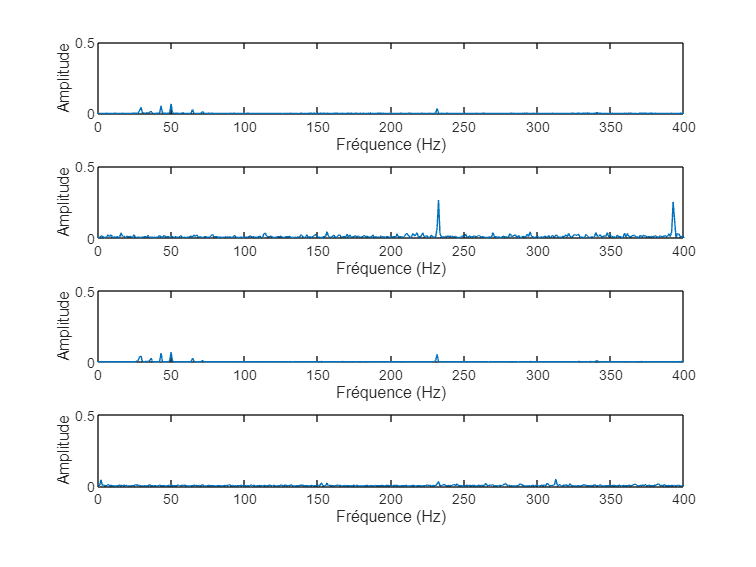

%------------------ Healthy signal ------------------------
figure(2)
subplot(4, 1, 1)
plot_fft(xNormal,Fs); %This function calculates the Fast Fourier Transform (FFT) (Amplitude as a function of frequency)
xlabel('Fréquence (Hz)'); % xlabel;
ylabel('Amplitude'); % ylabel;
xlim([0 400])
ylim([0 0.5])

%------------------ faulty signal outer ------------------------
subplot(4, 1, 2)
plot_fft(xInner,Fs); %This function calculates the Fast Fourier Transform (FFT) (Amplitude as a function of frequency)
xlabel('Fréquence (Hz)'); % xlabel;
ylabel('Amplitude'); % ylabel;
xlim([0 400])
ylim([0 0.5])



 %------------------ faulty signal inner ------------------------
subplot(4, 1, 3)
plot_fft(xOuter,Fs); %This function calculates the Fast Fourier Transform (FFT) (Amplitude as a function of frequency)
xlabel('Fréquence (Hz)'); % xlabel;
ylabel('Amplitude'); % ylabel;
xlim([0 400])
ylim([0 0.5])



 %------------------ faulty signal inner ------------------------
subplot(4, 1, 4)
plot_fft(xBall,Fs); %This function calculates the Fast Fourier Transform (FFT) (Amplitude as a function of frequency)
xlabel('Fréquence (Hz)'); % xlabel;

ylabel('Amplitude'); % ylabel;
xlim([0 400])
ylim([0 0.5])

% %% =======================================================================================
% %                            Extracting Condition Indicators
% %=========================================================================================

ind_healthy = 1.0e+03 *

    0.0001    0.0000    0.0036    0.0004   -0.0004    0.0000    0.0001    3.0986
    0.0001    0.0000    0.0036    0.0004   -0.0004    0.0000    0.0001    3.0643
    0.0001   -0.0000    0.0036    0.0004   -0.0004    0.0000    0.0001    3.0845
    0.0001    0.0000    0.0035    0.0004   -0.0004    0.0000    0.0001    3.0353
    0.0001    0.0000    0.0034    0.0004   -0.0004    0.0000    0.0001    3.0093
    0.0001    0.0000    0.0033    0.0004   -0.0004    0.0000    0.0001    2.9766
    0.0001   -0.0000    0.0036    0.0005   -0.0004    0.0000    0.0001    3.0461
    0.0001    0.0001    0.0035    0.0004   -0.0004    0.0000    0.0001    3.0680
    0.0001    0.0000    0.0034    0.0004   -0.0004    0.0000    0.0001    3.0608
    0.0001    0.0000    0.0034    0.0003   -0.0003    0.0000    0.0001    3.0716


ind_inner = 1.0e+03 *

    0.0002   -0.0001    0.0049    0.0016   -0.0015    0.0000    0.0002    4.5269
    0.0002   -0.0000    0.0062    0.0026   -0.0014    0.0000    0.0002    4.6055
    0.0002   -0.0002    0.0062    0.0020   -0.0024    0.0000    0.0002    4.5821
    0.0002   -0.0000    0.0107    0.0032   -0.0027    0.0001    0.0002    4.6195
    0.0002    0.0001    0.0080    0.0026   -0.0019    0.0001    0.0002    4.5685
    0.0002    0.0003    0.0137    0.0038   -0.0024    0.0001    0.0002    4.6521
    0.0002   -0.0001    0.0084    0.0027   -0.0027    0.0001    0.0002    4.5139
    0.0002   -0.0002    0.0082    0.0024   -0.0025    0.0001    0.0002    4.5712
    0.0002   -0.0000    0.0084    0.0025   -0.0031    0.0001    0.0002    4.5123
    0.0002   -0.0001    0.0056    0.0023   -0.0019    0.0001    0.0002    4.4394


ind_outer = 1.0e+03 *

    0.0001   -0.0000    0.0036    0.0005   -0.0004    0.0000    0.0001    3.3983
    0.0001   -0.0000    0.0034    0.0004   -0.0004    0.0000    0.0001    3.4147
    0.0001    0.0000    0.0037    0.0005   -0.0005    0.0000    0.0001    3.4221
    0.0001   -0.0001    0.0036    0.0004   -0.0004    0.0000    0.0001    3.4402
    0.0001   -0.0000    0.0035    0.0004   -0.0005    0.0000    0.0001    3.4209
    0.0001    0.0000    0.0036    0.0004   -0.0004    0.0000    0.0001    3.4664
    0.0001   -0.0001    0.0036    0.0004   -0.0005    0.0000    0.0001    3.4150
    0.0001   -0.0000    0.0035    0.0004   -0.0004    0.0000    0.0001    3.4580
    0.0001   -0.0001    0.0035    0.0004   -0.0004    0.0000    0.0001    3.4438
    0.0001    0.0000    0.0035    0.0005   -0.0004    0.0000    0.0001    3.4901


ind_ball = 1.0e+03 *

    0.0001    0.0001    0.0042    0.0006   -0.0005    0.0000    0.0001    3.5903
    0.0001    0.0000    0.0039    0.0006   -0.0006    0.0000    0.0001    3.5689
    0.0001   -0.0000    0.0040    0.0006   -0.0006    0.0000    0.0001    3.5893
    0.0001   -0.0000    0.0044    0.0006   -0.0007    0.0000    0.0001    3.5043
    0.0001    0.0000    0.0043    0.0006   -0.0006    0.0000    0.0001    3.5677
    0.0001   -0.0000    0.0042    0.0008   -0.0006    0.0000    0.0001    3.6108
    0.0001   -0.0000    0.0039    0.0005   -0.0005    0.0000    0.0001    3.5873
    0.0001    0.0000    0.0042    0.0006   -0.0006    0.0000    0.0001    3.6122
    0.0001   -0.0001    0.0041    0.0005   -0.0006    0.0000    0.0001    3.5910
    0.0001   -0.0001    0.0042    0.0005   -0.0007    0.0000    0.0001    3.5500


# **Feature Extraction**

In this section you extract features from the signals and implement machine learning and deep learning solutions to classify signals as healthy, having inner race faults, ball fault or having outer race faults. Use the `features_extraction` function (**In the function folder**) to extract features from all the signals.

- For time domain, use root-mean-square value, impulse factor, standard deviation, and clearance factor as features.

- For frequency domain, use median frequen

- cy.

%%=============================== Data Set ================================
ind_healthy = features_extraction(healthy,Fs) % returns features extracted from signal x sampled at a rate fs (x,fs).
ind_inner = features_extraction(innerfault,Fs)
ind_outer = features_extraction(outerfault,Fs)
ind_ball = features_extraction(ballfault,Fs)

### Prepare the data

% build X_Data vector of data set and their labels Y_Data

Data_Set = 200×2 table
      X_Data      Y_Data 
    __________    _______

    1×8 double    Healthy
    1×8 double    Healthy
    1×8 double    Healthy
    1×8 double    Healthy
    1×8 double    Healthy
    1×8 double    Healthy
    1×8 double    Healthy
    1×8 double    Healthy
    1×8 double    Healthy
    1×8 double    Healthy
    1×8 double    Healthy
    1×8 double    Healthy
    1×8 double    Healthy
    1×8 double    Healthy
    1×8 double    Healthy
    1×8 double    Healthy


X_Data=[ind_healthy;ind_inner;ind_outer;ind_ball];

Y_Data = categorical([repmat("Healthy",50,1);repmat("Inner",50,1);repmat("Outer",50,1);repmat("Ball",50,1)]);

Data_Set = table(X_Data,Y_Data)

meanObs = 1.0e+03 *

    0.0001   -0.0000    0.0044    0.0009   -0.0008    0.0000    0.0001    3.6117


stdObs =     0.0647    0.0612    1.4175    0.7256    0.6856    0.0215    0.0647  475.7982


### Normalize data

**ML**  models are sensitive to the scaling of the features, so it's important to normalize the data before training. The code below will use z-scores to normalize the data.

First, calculate the mean and standard deviation of each feature. These are saved to variables so the same normalization can be applied to both the training and test set.

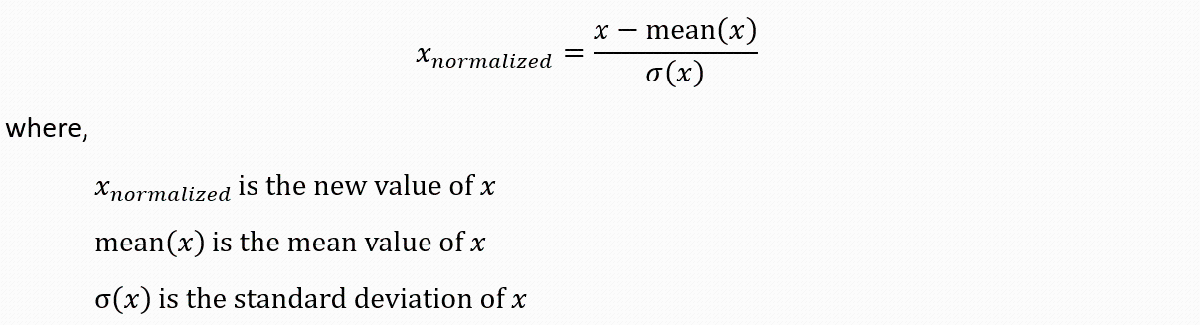

**use the normalization formula for the X_Data**

meanObs = mean(X_Data) %mean of X

N_Data = 200×2 table
    Normalised_Data    Y_Data 
    _______________    _______

      1×8 double       Healthy
      1×8 double       Healthy
      1×8 double       Healthy
      1×8 double       Healthy
      1×8 double       Healthy
      1×8 double       Healthy
      1×8 double       Healthy
      1×8 double       Healthy
      1×8 double       Healthy
      1×8 double       Healthy
      1×8 double       Healthy
      1×8 double       Healthy
      1×8 double       Healthy
      1×8 double       Healthy
      1×8 double       Healthy
      1×8 double       Healthy


stdObs = std(X_Data)  % standard deviation of X

Then calculate the z-score for the training and test set.

Normalised_Data= (X_Data - meanObs) ./ stdObs;

N_Data = table(Normalised_Data,Y_Data)

idx =      1     6     7     4     8     3     5     2


# `Select features`

**ML** functions can take a significant amount of time to select a final model. Therefore, it's helpful to first remove the features that you're confident will not help predict the response. This will decrease the training time for each model, making the overall process faster. 

[`idx`](https://fr.mathworks.com/help/stats/fscchi2.html#mw_1dc624f2-d785-47d9-bd35-3820a00dfa48_sep_shared-idx) `= `[fscchi2](https://fr.mathworks.com/help/stats/fscchi2.html)`(`[`X`](https://fr.mathworks.com/help/stats/fscchi2.html#mw_1dc624f2-d785-47d9-bd35-3820a00dfa48_sep_shared-X)`,`[`Y`](https://fr.mathworks.com/help/stats/fscchi2.html#mw_1dc624f2-d785-47d9-bd35-3820a00dfa48_sep_shared-Y)`)` ranks predictors in `X` using the response variable `Y`.

% Use chi-squared tests to rank features by importance
idx = fscchi2(Normalised_Data, Y_Data);
idx

Selected_Data = 200×2 table
                             S_Data                             Y_Data 
    ________________________________________________________    _______

    -0.74467    -0.65871    -0.74452    -0.62047     -1.0783    Healthy
    -0.75469    -0.66371    -0.75498    -0.61772     -1.1504    Healthy
    -0.76327    -0.66763    -0.76324    -0.71144      -1.108    Healthy
    -0.76649    -0.66923    -0.76663    -0.59429     -1.2114    Healthy
    -0.77934    -0.67519    -0.77935    -0.64115     -1.2661    Healthy
     -0.7762    -0.67395    -0.77669    -0.70868     -1.3349    Healthy
    -0.75908    -0.66577    -0.75931    -0.55018     -1.1887    Healthy
     -0.7576    -0.66493    -0.75754    -0.62736     -1.1428    Healthy
    -0.75243    -0.66252    -0.75248    -0.67423     -1.1579    Healthy
    -0.75052    -0.66161    -0.75057    -0.72522     -1.1353    Healthy
     -0.7464    -0.65972    -0.74663   


% Create new training set using top 5 features
S_Data = Normalised_Data(:, idx(1:5));
Selected_Data = table(S_Data, Y_Data);
Selected_Data

N_Data_holdout = Hold-out cross validation partition
   NumObservations: 200
       NumTestSets: 1
         TrainSize: 140
          TestSize: 60

trainingData = 140×2 table
                             S_Data                             Y_Data 
    ________________________________________________________    _______

    -0.74467    -0.65871    -0.74452    -0.62047     -1.0783    Healthy
    -0.75469    -0.66371    -0.75498    -0.61772     -1.1504    Healthy
    -0.76649    -0.66923    -0.76663    -0.59429     -1.2114    Healthy
    -0.77934    -0.67519    -0.77935    -0.64115     -1.2661    Healthy
     -0.7762    -0.67395    -0.77669    -0.70868     -1.3349    Healthy
     -0.7576    -0.66493    -0.75754    -0.62736     -1.1428    Healthy
    -0.75052    -0.66161    -0.75057    -0.72522     -1.1353    Healthy
    -0.75215    -0.66242    -0.75227    -0.63012     -1.2496    Healthy
    -0.77751    -0.67432    -0.77747    -0.72522      -1.175    Healthy
    -0.76918    -0.67057    -0.76947    -0.66044     -1.3314    Healthy
    -0.76019    -0.66634    -0.76051    

testData = 60×2 table
                             S_Data                             Y_Data 
    ________________________________________________________    _______

    -0.76327    -0.66763    -0.76324    -0.71144      -1.108    Healthy
    -0.75908    -0.66577    -0.75931    -0.55018     -1.1887    Healthy
    -0.75243    -0.66252    -0.75248    -0.67423     -1.1579    Healthy
     -0.7464    -0.65972    -0.74663     -0.6949    -0.99184    Healthy
    -0.77981    -0.67551    -0.78002    -0.64115     -1.1897    Healthy
    -0.78102    -0.67609    -0.78126    -0.69076      -1.345    Healthy
     -0.7645    -0.66834    -0.76475     -0.6439     -1.2038    Healthy
    -0.76987    -0.67072    -0.76979    -0.70455     -1.2699    Healthy
     -0.7911    -0.68072    -0.79125    -0.72109     -1.3057    Healthy
    -0.76637    -0.66917     -0.7665    -0.51297     -1.2022    Healthy
    -0.76516    -0.66859    -0.76527     -0.6

Nous avons laissé uniquement les top 5 features qui nous sont importantes dans la prédiction du type de défaillance.

# **Partition into Training and Testing Sets**

**Reserve 30% of the data set for testing.**

### Using the table height for random splitting

Let's start by looking at a **regression problem**, where you want to **predict** the **indicator values** from the table `healthData`. The first step in solving this problem is randomly splitting the data into a training/validation set and a test set. To do that first split, you need to: 

- Use the `cvpartition` function with the height of the table for random splitting. This operation will create a cvpartition object.

- Apply the `training` and `test` functions to extract the indices to the training/validation and test samples.

- Create** two separate data sets** for training/validation and test with the indices from step 2.

An earlier reading demonstrated how to use the `cvpartition` function with the height of the data set as the first input and the "Holdout" option. The result of the `cvpartition` function will be a partition, containing *randomly* selected indices for the training and test data.

N_Data_holdout = cvpartition(height(Selected_Data),"Holdout",0.3)

To extract these indices, apply the training and test functions to `healthData_holdout`. The following lines of code go one step further and create separate tables for the training and test data sets.

trainingData = Selected_Data(training(N_Data_holdout),:)
testData = Selected_Data(test(N_Data_holdout),:)


**Execute *****this section***** several times and observe how the data sets change, especially the test set.  **

# `Train a multiclass model`

## Prepare the data

% %% ========================================================================
% %                             Train Model
% %==========================================================================
% Build x for the training set
X_train = trainingData.S_Data;

% Build x for the test set
X_test = testData.S_Data;

% Build y label for the training set
Y_train = trainingData.Y_Data;

% Build y label for the test set
Y_test = testData.Y_Data;


mdl =   ClassificationECOC
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Ball    Healthy    Inner    Outer]
           ScoreTransform: 'none'
           BinaryLearners: {7×1 cell}
               CodingName: 'binarycomplete'


  Properties, Methods


## One vs. One Classification

The strategy called "One vs. All" classification can be used for multiclass classification by training multiple models and leveraging them together. 

Another variant is called "One vs. One" classification. Here, a binary classification model is trained on each pair of classes. Consider the example below with three classes:

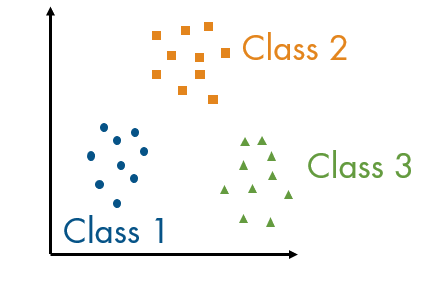

Three models will be trained using each pair of classes. In other words, each model uses a different subset of the data.

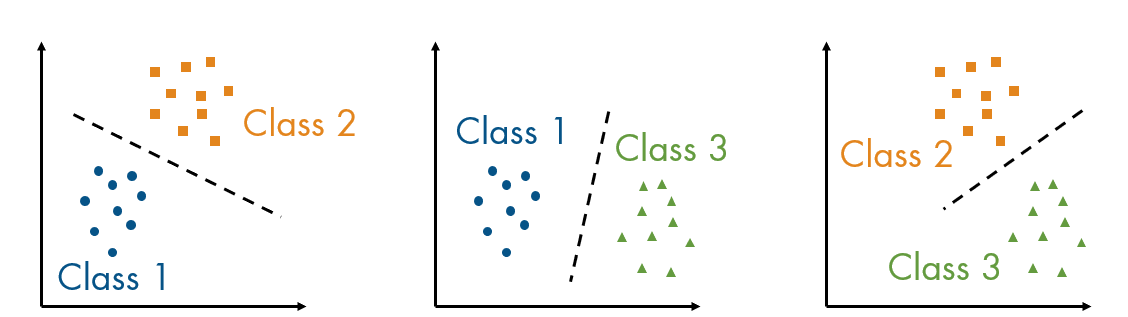

When predicting the class for a new datapoint, the binary predictions for each model are calculated, and the most commonly assigned class is chosen. 

In general, the One vs. One strategy will require a larger number of models than the One vs All strategy since a model is trained for each pair. 

The performance of each strategy will depend on multiple factors like the number of observations and the number of classes. 

**Try out multiple strategies and choose one that works well with your data.**

The MATLAB function to train multiclass models is `fitcecoc`. The letters "ECOC" stand for "Error-Correcting Output Codes". You can read [the documentation](https://www.mathworks.com/help/stats/fitcecoc.html) for more information.

This function works similarly to the other classification functions like `fitcknn`, but there are a few unique options you need to specify.

- `"Learners"` allows you to set the type of model, such as `"svm"`, `"knn"`, or `"tree"`.

- `"Coding"` allows you to specify the strategy used, such as `"onevsall"` or `"onevsone"`. See the documentation for a description of all the available options.

mdl = fitcecoc(X_train,Y_train, ...
    "Learners","svm", ...
    "Coding","binarycomplete")

accuracy = 96.6667

## Evaluate a multiclass model

### Accuracy

Calculate the accuracy of the model by comparing the true classes with the predicted classes.

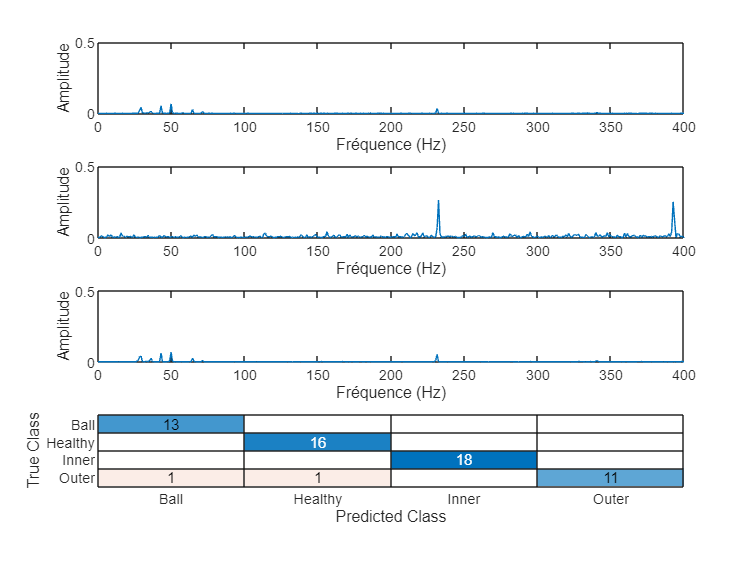

% % Get the true and predicted classes
trueLabel = Y_test;

predictLabel = predict(mdl, X_test);

% Calculate the accuracy. Multiply by 100 to report the value as a percentage

Accuracy = 96.67%

ans = 6×5 table
               Precision    Recall     Fallout     Specificity      F1   
               _________    _______    ________    ___________    _______

    Ball        0.92857           1    0.021277      0.97872      0.96296
    Healthy     0.94118           1    0.022727      0.97727       0.9697
    Inner             1           1           0            1            1
    Outer             1     0.84615           0            1      0.91667
    Avg         0.96744     0.96154    0.011001        0.989      0.96233
    WgtAvg      0.96884     0.96667    0.010671      0.98933      0.96584


accuracy = sum(trueLabel == predictLabel) / length(trueLabel) * 100;
accuracy

### Confusion matrix

The confusion matrix for a multiclass model will have a row and column for each class. In this case, that means a 6x6 matrix. You can look at the raw counts in the confusion matrix by setting "absolute" as the normalization option. If you prefer to get percentages, you can normalize the matrix either by row, column, or total count.

confusionchart(trueLabel,predictLabel,"Normalization","absolute");

### Class-specific metrics

Metrics such as precision and recall can be calculated for each class using the counts in the confusion matrix. To help out, you've been provided with a custom function `cMetrics` that takes the labels as inputs and returns the class-specific metrics in a table.

cMetrics(trueLabel,predictLabel)

Nous avons trouvé que le modèle KNN est le meilleur modèle à 100% d'accuracy, il prédit de manière parfaite les 4 signaux.

# **Use the Trained Model to Predict new Data**

***Congratulations,*** you just selected and trained an optimized model with a single line of code! Now you need to evaluate the model with new data. 

**Now it's your turn: **Load  the **"Evaluation_data.mat"** set, and try to apply the same pre-processing steps to the Evaluation_data set, predict the class labels, and evaluate the performance.

% % load the evaluation data
 load("Evaluation_data.mat");
 addpath('Functions');

## Test Results

### Preprocess the evaluate Data

Before you can run the model on the Evaluation data. you'll need to preprocess the data.

- **(extract and normalize selected features)**

% % put your code here
% Extract features from the evaluation data (replace this with your actual feature extraction code)
ind_S1 = features_extraction(S1, Fs);
ind_S2 = features_extraction(S2, Fs);
ind_S3 = features_extraction(S3, Fs);
ind_S4 = features_extraction(S4, Fs);
ind_S5 = features_extraction(S5, Fs);
ind_S6 = features_extraction(S6, Fs);
ind_S7 = features_extraction(S7, Fs);

% Normalize the features extracted from the evaluation data using the same mean and standard deviation as the training data
Normalised_S1 = (ind_S1 - meanObs) ./ stdObs;
Normalised_S2 = (ind_S2 - meanObs) ./ stdObs;
Normalised_S3 = (ind_S3 - meanObs) ./ stdObs;
Normalised_S4 = (ind_S4 - meanObs) ./ stdObs;
Normalised_S5 = (ind_S5 - meanObs) ./ stdObs;
Normalised_S6 = (ind_S6 - meanObs) ./ stdObs;
Normalised_S7 = (ind_S7 - meanObs) ./ stdObs;

### Used the Trained Models to Make Predictions

Now you can use your exported model's  to predict which of the signals in theevaluation data set are healthy, inner fault, outer fault or ball fault.

% % put your code here
S1_evaluation = Normalised_S1(:, idx(1:5));
S2_evaluation = Normalised_S2(:, idx(1:5));
S3_evaluation = Normalised_S3(:, idx(1:5));
S4_evaluation = Normalised_S4(:, idx(1:5));

predicted_labels_S1 = categorical
     Outer 


S5_evaluation = Normalised_S5(:, idx(1:5));
S6_evaluation = Normalised_S6(:, idx(1:5));

predicted_labels_S2 = categorical
     Healthy 


S7_evaluation = Normalised_S7(:, idx(1:5));


predicted_labels_S3 = categorical
     Inner 



% Predict class labels for the evaluation data using the trained model

predicted_labels_S4 = categorical
     Outer 


predicted_labels_S1 = predict(mdl, S1_evaluation);
predicted_labels_S1

predicted_labels_S5 = categorical
     Healthy 


predicted_labels_S2 = predict(mdl, S2_evaluation);
predicted_labels_S2

predicted_labels_S6 = categorical
     Inner 


predicted_labels_S3 = predict(mdl, S3_evaluation);
predicted_labels_S3

predicted_labels_S7 = categorical
     Ball 


predicted_labels_S4 = predict(mdl, S4_evaluation);
predicted_labels_S4
predicted_labels_S5 = predict(mdl, S5_evaluation);
predicted_labels_S5
predicted_labels_S6 = predict(mdl, S6_evaluation);
predicted_labels_S6
predicted_labels_S7 = predict(mdl, S7_evaluation);
predicted_labels_S7

### KNN EST LE MEILLEUR MODEL. Discriminant aussi.